# EEE3548 Exercise #3 Image Quality - Resolution (FWHM, Rayleigh Criteria)

## [23.04.14] [ImHyeonJeong]

#### Q1. Define the OTF of  an ideal imaging system, whose cut-off frequency is $k_c$ = 8 cycles per mm. Assume that a pixel is 0.005mm (N = 256). 

#### Plot the PSF of the system (intensity). What is the resolution of this camera defined by 1) the FWHM (Abbe's criterion) and 2) the Rayleigh's criterion? 

N = 256;
psize = 0.005; % delta_x, (mm)

kx = linspace(-1/2, 1/2, N)/psize; 
ky = linspace(-1/2, 1/2, N)/psize;
[KX, KY] = meshgrid(kx, ky);
kc = 8;

OTF = (KX.^2+KY.^2) < kc.^2;
PSF = ifftshift(ifft2(OTF)); 

% Jinc function 
PSF_center = abs(PSF(:,length(PSF)/2));
max_value = max(PSF_center);
min_value = min(PSF_center);

% Resolution by FWHM (Abbe's criterion)
fwhm_index = find(PSF_center >= max_value/2);
fwhm = (fwhm_index(end) - fwhm_index(1)) * psize;

% Resolution by Rayleigh's criterion
ray = (144-129) * psize;

% Resolution
R1 = ['Resolution by FWHM (Abbe''s criterion) : ' num2str(fwhm, '%.3f')];
R2 = ['Resolution by Rayleigh''s criterion : ' num2str(ray, '%.3f')];
fprintf('%s\n%s', R1, R2);

Resolution by FWHM (Abbe's criterion) : 0.080
Resolution by Rayleigh's criterion : 0.075

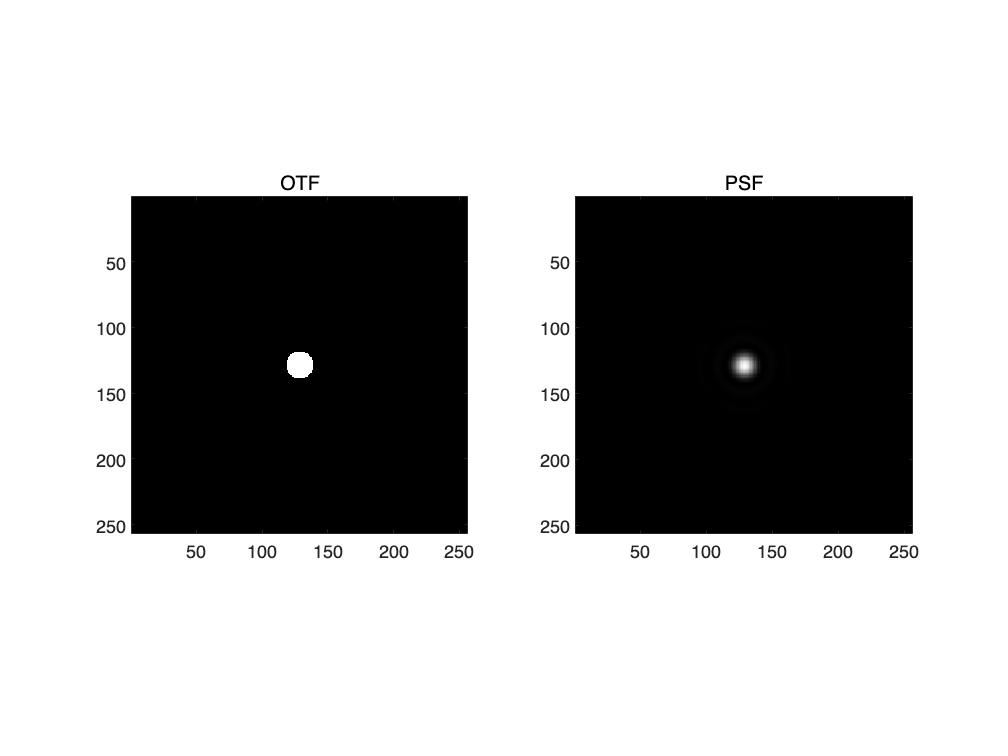

% Plot
figure(1);
subplot(121), imagesc(abs(OTF).^2); colormap gray; axis image; title('OTF');
subplot(122), imagesc(abs(PSF).^2); colormap gray; axis image; title('PSF');

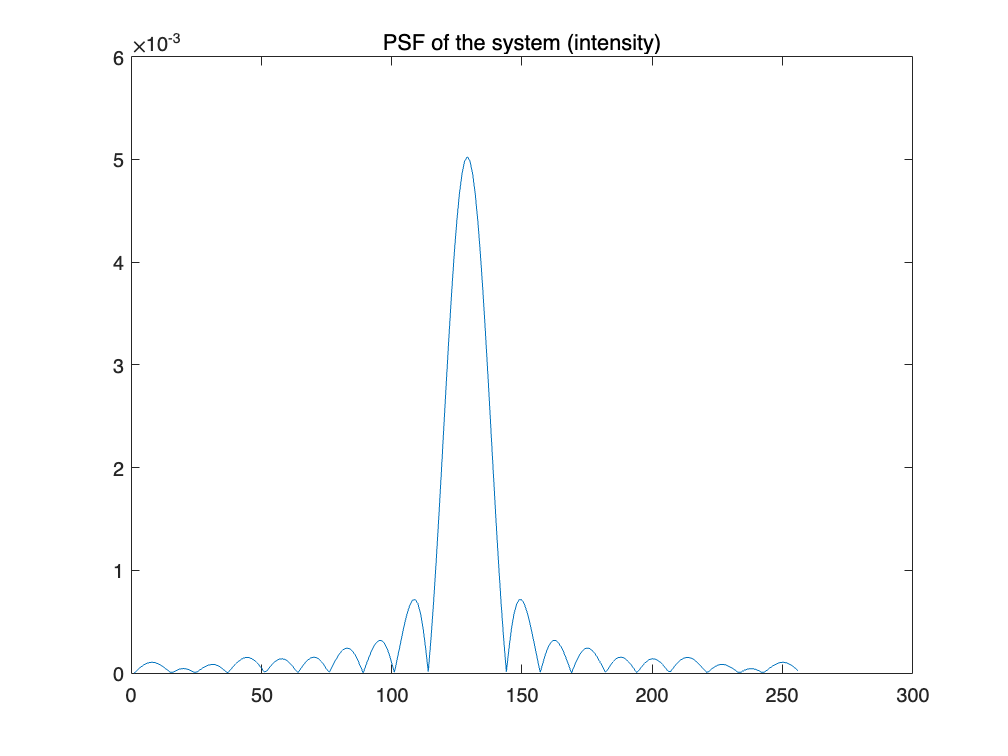

figure(2);
plot(PSF_center); title('PSF of the system (intensity)');

### **Answer**

1) Resolution of this camera defined by the FWHM (Abbe's criterion) : 0.080 (mm)

2) Resolution of this camera defined by the Rayleigh's criterion : 0.075 (mm)

#### Q2. Download "1.4.07.tiff" from [https://sipi.usc.edu/database/download.php?vol=textures&img=1.4.07](https://sipi.usc.edu/database/download.php?vol=textures&img=1.4.07)

#### Load the image, plot the image and its Fourier spectrum.

#### Downsample the image by a factor of 10 (one out of every 10 samples), plot the image and its Fourier spectrum. What do you see?

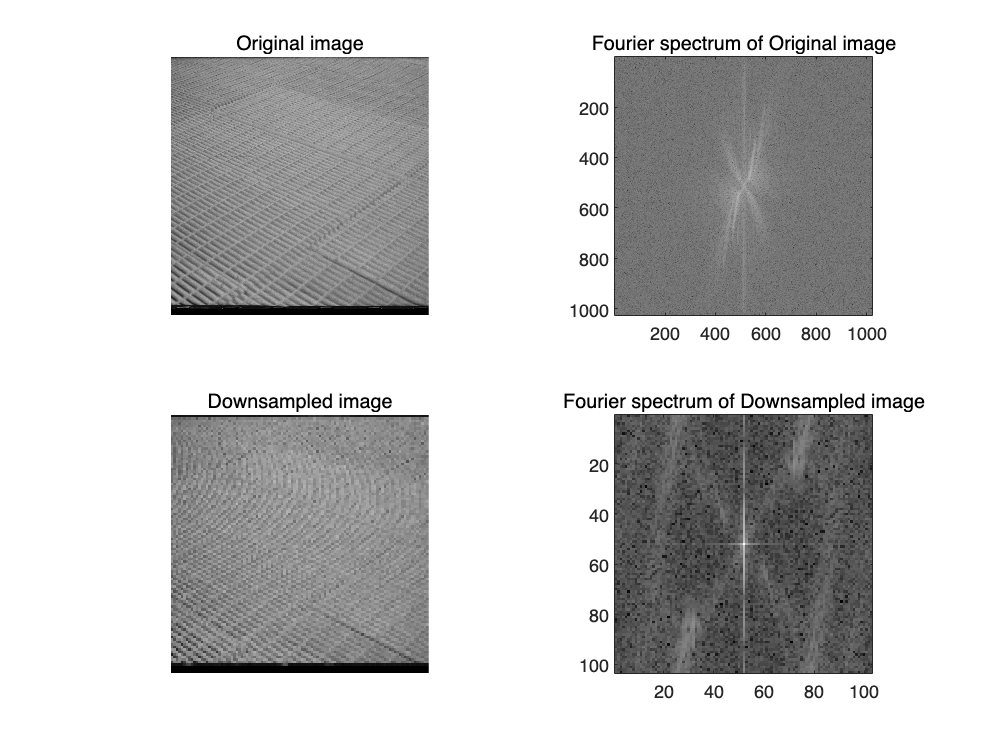

% Original image
img = imread('1.4.07.tiff');
FT_img = abs(fftshift(fft2(img)));

% Downsampled image by a factor of 10
img_down = img(1:10:end,1:10:end);
FT_img_down = abs(fftshift(fft2(img_down)));

figure(3);
subplot(221); imshow(img); colormap gray; axis image; title('Original image');
subplot(222); imagesc(log(FT_img)); colormap gray; axis image; title('Fourier spectrum of Original image');
subplot(223); imshow(img_down); colormap gray; axis image; title('Downsampled image');
subplot(224); imagesc(log(FT_img_down)); colormap gray; axis image; title('Fourier spectrum of Downsampled image');

### **Discussion**

Comparing the downsampled image to the original image, it can be seen that the size of the pixels constituting the image has decreased. This is because the resolution of the image is reduced due to downsampling, and the frequency range that can be expressed is reduced. That is, the image cannot express the high frequency area (thin line, etc.) well. When the downsampled image is reconstructed, several artifacts are generated and a blurry image is expected to be restored compared to the original image. It seems to be a kind of aliasing effect. The fourier spectrum domain of the downsampled image was also reduced by a factor of 10. In addition, information in the low frequency region (including DC component) is preserved. However, in the high frequency region (outer part), white parts that were not present in the original image can be seen. Through this, it can be interpreted that the high frequency details have disappeared.

#### Q3. In your test image, add zero-mean white gaussian noise to change the SNR of the image. Use imnoise function (read its description) to choose appropriate value of noise variance. You need to install image processing toolbox of MATLAB. Plot the Fourier spectrum of the noisy images, explain what you see. 

% Original image
img = imread('1.4.07.tiff');
I = double(img) / 255; % uint8 [0,255] -> double [0,1]
v = var(I(:)); % img variance
m = mean(I(:)); % img mean

% Noised image
img_noise = imnoise(img,'gaussian', 0, v); % zero-mean wgn img
FT_img_noise = abs(fftshift(fft2(img_noise)));
I_noise = double(img_noise) / 255; 
std_noise = std(I_noise(:)-I(:)); % noise std

% The SNR value
SNR = m / sqrt(v); % using gaussian variance 
fprintf('The SNR value is %0.4f', SNR);

The SNR value is 4.3434

snr = m / std_noise; % using definition
fprintf('The SNR value is %0.4f', snr);

The SNR value is 4.3850

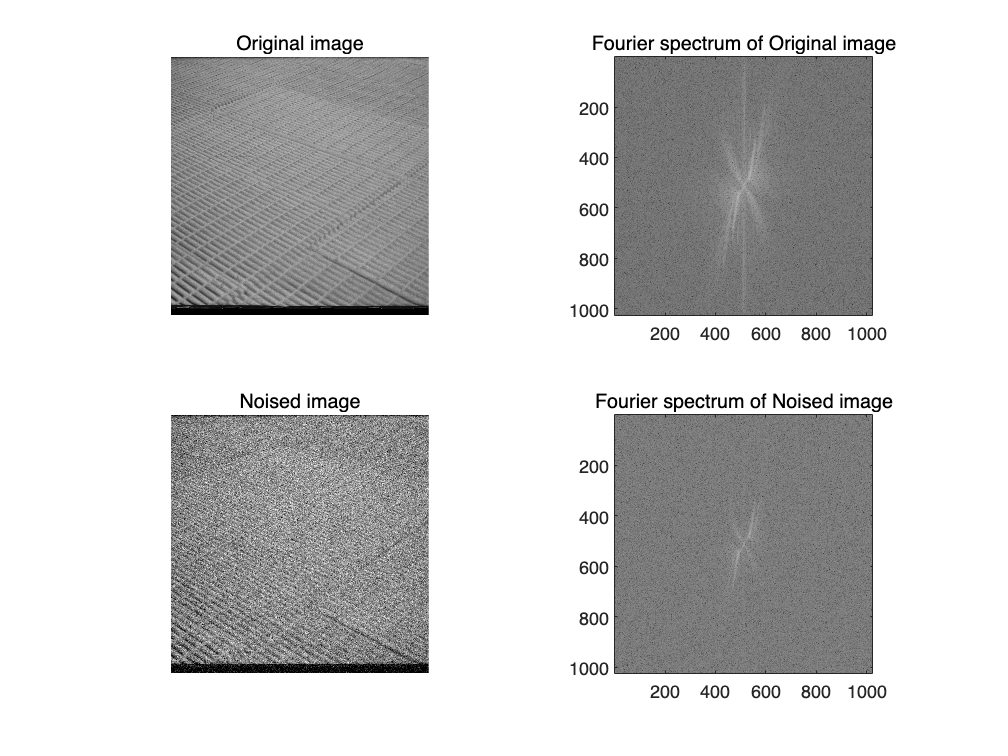

% Plot
figure(4);
subplot(221); imshow(img); colormap gray; axis image; title('Original image');
subplot(222); imagesc(log(FT_img)); colormap gray; axis image; title('Fourier spectrum of Original image');
subplot(223); imshow(img_noise); colormap gray; axis image; title('Noised image');
subplot(224); imagesc(log(FT_img_noise)); colormap gray; axis image; title('Fourier spectrum of Noised image');

### **Discussion**

Comparing the noised image with zero-mean white gaussian noise added to the original image, it was confirmed that the image became noisy because many parts of the image were damaged. In addition, it can be interpreted that when noise is added, not only high frequency components but also information in the low frequency components are lost through the reduction of the white area in the middle of the fourier spectrum of the noised image.